clc, clear, close all;

## Generated EMG signal

base_sample_rate = 1000;
emg_sample_rate = 1000;
samples = 1:100000;

AddPaths()

Linux


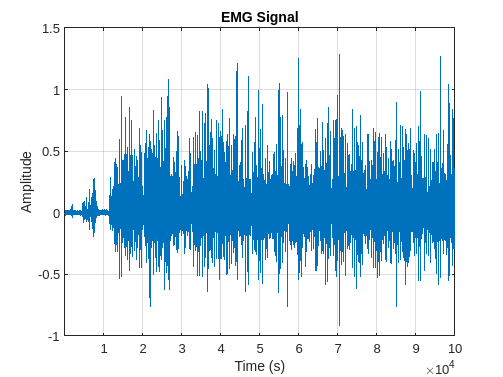


emg_file = 'EMG_SECOND_PLAY_CHOPIN_C.txt';
[~, emg_signal, ~] = ReadData(emg_file, emg_sample_rate, base_sample_rate);

n = 12; VCC = 3; Gemg = 1000;
DigTomV = @(adc) (((adc./2.^n - 1/2) .* VCC) ./ Gemg) * 1000;

emg_signal = DigTomV(emg_signal(samples)');

% Plot the EMG signal
figure;
plot(samples, emg_signal);
xlabel('Time (s)'); ylabel('Amplitude');
title('EMG Signal');
xlim([samples(1), samples(end)])
grid on;

# Noise

% Parameters
fs = 1000;              % Sampling frequency in Hz
T = length(samples)/fs; % Duration of the signal in seconds
t = (0:(fs*T-1))/fs;    % Time vector

### Powerline interferance

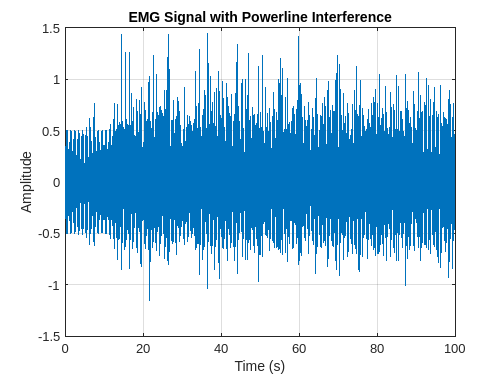

% Parameters
powerline_freq = 50;    % Powerline frequency in Hz (or 60 Hz if applicable)
amplitude = 0.50;       % Amplitude of the interference signal (adjust as needed)

% Generate powerline interference
powerline = @(t) sin(2 .* pi .* powerline_freq .* t) .* sin(2 .* pi .* 1./2 .* t);
powerline_interference = amplitude * powerline(t);

% Add powerline interference to the EMG signal
emg_with_powerline = emg_signal + powerline_interference;

% Plot the EMG signal with powerline interference
figure;
plot(t, emg_with_powerline);
xlabel('Time (s)'); ylabel('Amplitude');
title('EMG Signal with Powerline Interference');
grid on;

### Baseline oscillations

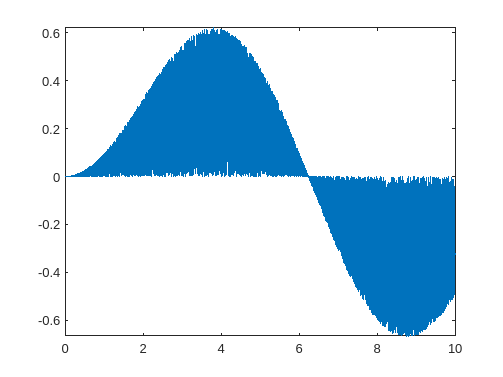

% Parameters
baseline_freq = 0.1;        % Frequency of the baseline oscillation in Hz
baseline_amplitude = 0.50;  % Amplitude of the baseline oscillation

% Generate baseline oscillations (low-frequency drift)
baseline = @(t) (sin(3.78 .* baseline_freq .* t) + sin(2 .* pi .* baseline_freq .* t)) .* sin(rand() .* baseline_freq .* t);
baseline_oscillation = baseline_amplitude * baseline(t);

% Add baseline oscillations to the EMG signal
emg_with_baseline = emg_signal + baseline_oscillation;

% Plot the EMG signal with baseline oscillations

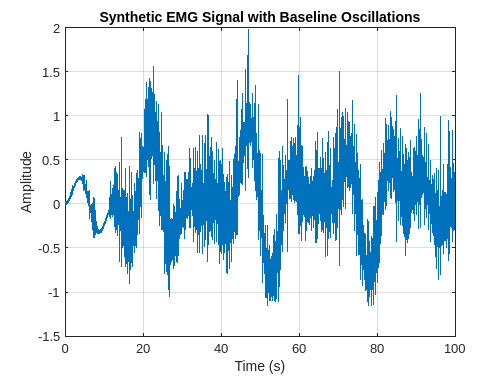

figure;
plot(t, emg_with_baseline);
xlabel('Time (s)'); ylabel('Amplitude');
title('Synthetic EMG Signal with Baseline Oscillations');
grid on;

### Complete noise signal

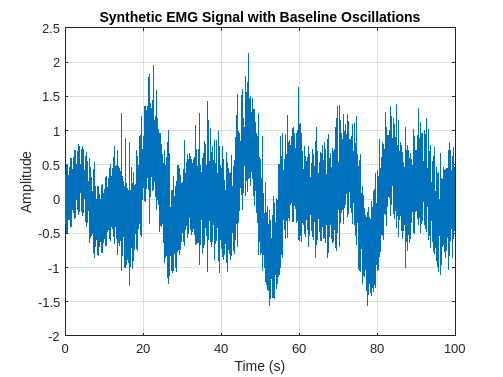

% Add noise to the EMG signal
emg_with_noise = emg_signal + powerline_interference + baseline_oscillation;

% Plot the EMG signal with noise
figure;
plot(t, emg_with_noise);
xlabel('Time (s)'); ylabel('Amplitude');
title('Synthetic EMG Signal with Baseline Oscillations');
grid on;

# Filter

% Parameters
fs = 1000;      % Sampling frequency in Hz
N = fs / 50;    % Delay in samples to ensure nulls at multiples of 50 Hz
g = -1;         % Gain of the delayed signal
% Note if g is

### FFC concept

% Example input signal
x = (1:100)';   % Column vector signal

% Create delayed signal
delayed_signal = [zeros(N, 1); x(1:end-N)];

% Apply feed-forward comb filter
y = x + g * delayed_signal;

% Display the results
disp(['Original signal:', 'Filtered signal:']);

Original signal:Filtered signal:


disp([x, y]);

     1     1
     2     2
     3     3
     4     4
     5     5
     6     6
     7     7
     8     8
     9     9
    10    10
    11    11
    12    12
    13    13
    14    14
    15    15
    16    16
    17    17
    18    18
    19    19
    20    20
    21    20
    22    20
    23    20
    24    20
    25    20
    26    20
    27    20
    28    20
    29    20
    30    20
    31    20
    32    20
    33    20
    34    20
    35    20
    36    20
    37    20
    38    20
    39    20
    40    20
    41    20
    42    20
    43    20
    44    20
    45    20
    46    20
    47    20
    48    20
    49    20
    50    20
    51    20
    52    20
    53    20
    54    20
    55    20
    56    20
    57    20
    58    20
    59    20
    60    20
    61    20
    62    20
    63    20
    64    20
    65    20
    66    20
    67    20
    68    20
    69    20
    70    20
    71    20
    72    20
    73    20
    74    20
    75    20
    76    20
    77    20

### FFC response

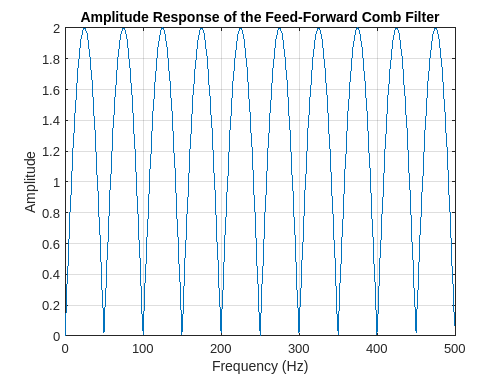

% Create the filter coefficients
b = [1, zeros(1, N-1), g];  % Feed-forward coefficients
a = 1;  % Feed-back coefficients (since it's a feed-forward filter)

% Compute the frequency response
[H, f] = freqz(b, a, 1024, fs);  % Use fs to indicate the sampling frequency

% Plot the amplitude response
figure;
plot(f, abs(H));
xlabel('Frequency (Hz)');   ylabel('Amplitude');
title('Amplitude Response of the Feed-Forward Comb Filter');
grid on;

### Apply FFC

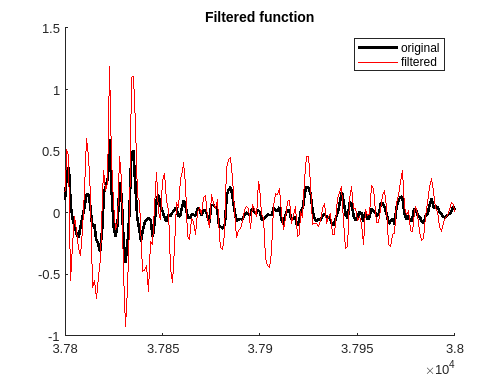

emg_filtered = filtfilt(b, a, emg_with_noise);
figure; hold on
plot(emg_signal, 'k', 'LineWidth', 2);
plot(emg_filtered, 'r', 'LineWidth', 1);
title("Filtered function");
legend("original", "filtered");
xlim([37800, 38000])
hold off

## Function

function [sync, muscle1, muscle2] = ReadData(filename_EMG, emg_sample_rate, base_sample_rate)
    % "column": ["index", "overbodig", "sync", "spier 1", "spier 2"]
    data = readmatrix(filename_EMG, 'Range', 4, 'Delimiter', '\t');
    sync = data(:, 3);
    muscle1 = data(:, 4);
    muscle2 = data(:, 5);
end